fid=fopen('images/lenna.256','r');
x=fread(fid,[256,256],'uchar');
fclose(fid);
x1=x(1:8,1:8);

hi


y1 = dct2(x1);

y = dct2(x);

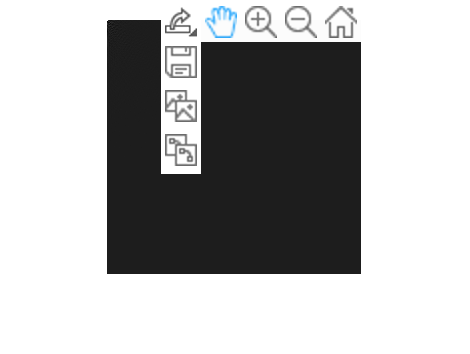

imshow(y, []);

Q = [16 11 10 16 24 40 51 61;     12 12 14 19 26 58 60 55;     14 13 16 24 40 57 69 56;     14 17 22 29 51 87 80 62;     18 22 37 56 68 109 103 77;     24 35 55 64 81 104 113 92;     49 64 78 87 103 121 120 101;     72 92 95 98 112 100 103 99];
quant_dct_x1 = round(y1 ./ Q);

Q_01 = 0.1*Q;
quant_dct_x1_01 = round(y1 ./ Q_01);